# Task 4: The spin-1/2 Heisenberg dimer under a magnetic field

We now take the system of the previous task and add an external magnetic field along the ${\bf z}$-axis. This problem is described by the Hamiltonian


$$\mathcal{H} = J {\bf S}_1 \cdot {\bf S}_2 - \gamma B (S_{1z}+S_{2z})\,,$$


In the following we set $J=1$.

# Subtask a

Write a few lines of code that deliver the matrix representation of $\mathcal{H}$ in the `product-$S_z$ basis' $$\{|S_1,M_1\rangle \otimes|S_2,M_2\rangle\}$$, for $\gamma B=1$. Solve the Schroedinger equation to obtain the energy eigenvalues and the corresponding eigenstates of $\mathcal{H}$. 

%add your code here
J = 1;
gammaB = 1;
Hamiltonian = (J*(S1x*S2x + S1y*S2y +S1z*S2z) - gammaB*(S1z + S2z))

Hamiltonian =    -0.7500         0         0         0
         0   -0.2500    0.5000         0
         0    0.5000   -0.2500         0
         0         0         0    1.2500


[V,D] = eig(Hamiltonian)

V =     1.0000         0         0         0
         0    0.7071    0.7071         0
         0   -0.7071    0.7071         0
         0         0         0    1.0000


D =    -0.7500         0         0         0
         0   -0.7500         0         0
         0         0    0.2500         0
         0         0         0    1.2500


Energy = eig(Hamiltonian);
EigState1 = V(:,1)

EigState1 =      1
     0
     0
     0


Energy1 = Energy(1)

Energy1 = -0.7500

EigState2 = V(:,2)

EigState2 =          0
    0.7071
   -0.7071
         0


Energy2 = Energy(2)

Energy2 = -0.7500

EigState3 = V(:,3)

EigState3 =          0
    0.7071
    0.7071
         0


Energy3 = Energy(3)

Energy3 = 0.2500

EigState4 = V(:,4)

EigState4 =      0
     0
     0
     1


Energy4 = Energy(4)

Energy4 = 1.2500

# Subtask b

Calculate the commutator $[\mathcal{H}, S_z]$ and then check explicitly that each eigenstate of $\mathcal{H}$ is also an eigenstate of the operator $S_z$. The corresponding eigenvalues are usually denoted by $M$. What is value of $$M$$ for each eigenstate of $\mathcal{H}$?

%add your code here
HamiltonianCommutatorSz = Hamiltonian * Sz - Sz * Hamiltonian

HamiltonianCommutatorSz =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


Ssquared * EigState1

ans =      2
     0
     0
     0


Ssquared * EigState2

ans =      0
     0
     0
     0


Ssquared * EigState3

ans =          0
    1.4142
    1.4142
         0


Ssquared * EigState4

ans =      0
     0
     0
     2


%Eigenvalues(M) = 2,0,2,2





# Subtask c

Plot the energy spectrum vs $\gamma B$, in the range $\gamma B \in [-5,5]$.

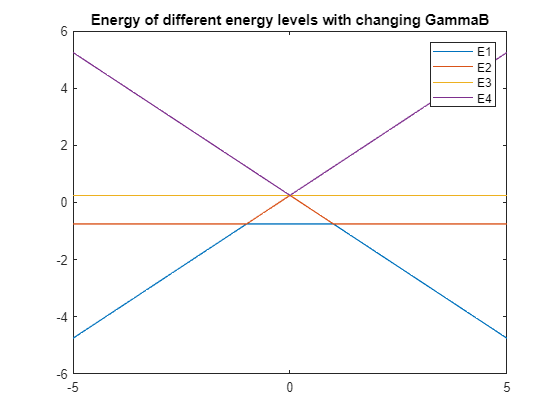

%add your code here
E1 = [];
E2 = [];
E3 = [];
E4 = [];

for gammaB = -5:0.1:5;
    Hamiltonian = (J*(S1x*S2x + S1y*S2y +S1z*S2z) - gammaB*(S1z + S2z));
    Energy = eig(Hamiltonian);
    E1 = [E1 Energy(1)];
    E2 = [E2 Energy(2)];
    E3 = [E3 Energy(3)];
    E4 = [E4 Energy(4)];
end;
y = -5:0.1:5;
plot(y,E1)
hold on
plot(y,E2)
hold on
plot(y,E3)
hold on
plot(y,E4)
hold on
legend('E1','E2','E3','E4')
title("Energy of different energy levels with changing GammaB")
hold off

# Subtask d

Plot the ${\bf ground~state}$ quantum mechanical expectation value of the operator $S_z$ vs $\gamma B$, in the range $\gamma B \in [-5,5]$. 

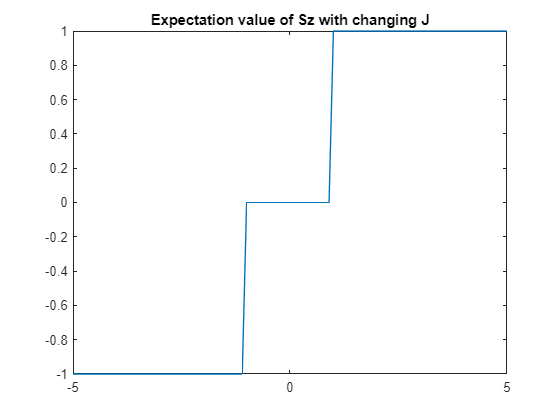

%add your code here
ExpectationSz = [];
for gammaB = -5:0.1:5;
    Hamiltonian = (J*(S1x*S2x + S1y*S2y +S1z*S2z) - gammaB*(S1z + S2z));
    [V,D] = eig(Hamiltonian);
    EigState1 = V(:,1);
    E1ExpectationSz = EigState1' * Sz * EigState1;
    ExpectationSz = [ExpectationSz E1ExpectationSz];
end
ExpectationSz;
x = -5:0.1:5;
plot(x,ExpectationSz)
title("Expectation value of Sz with changing J")